%%%% using PSD from eqn 1 page 311 of 
% https://www.researchgate.net/publication/242521284_Reduction_of_1f_Noise_by_Switched_Biasing_an_Overview

omega = linspace(0, 1e5, 10000);
t_capture = 1e-6; % average time in even band
t_emission = 2e-6;  % average time in odd band
beta = t_capture/t_emission;  %asymmetry paramter
omega_0 = 1/t_capture + 1/t_emission  %corner frequency

omega_0 = 1500000

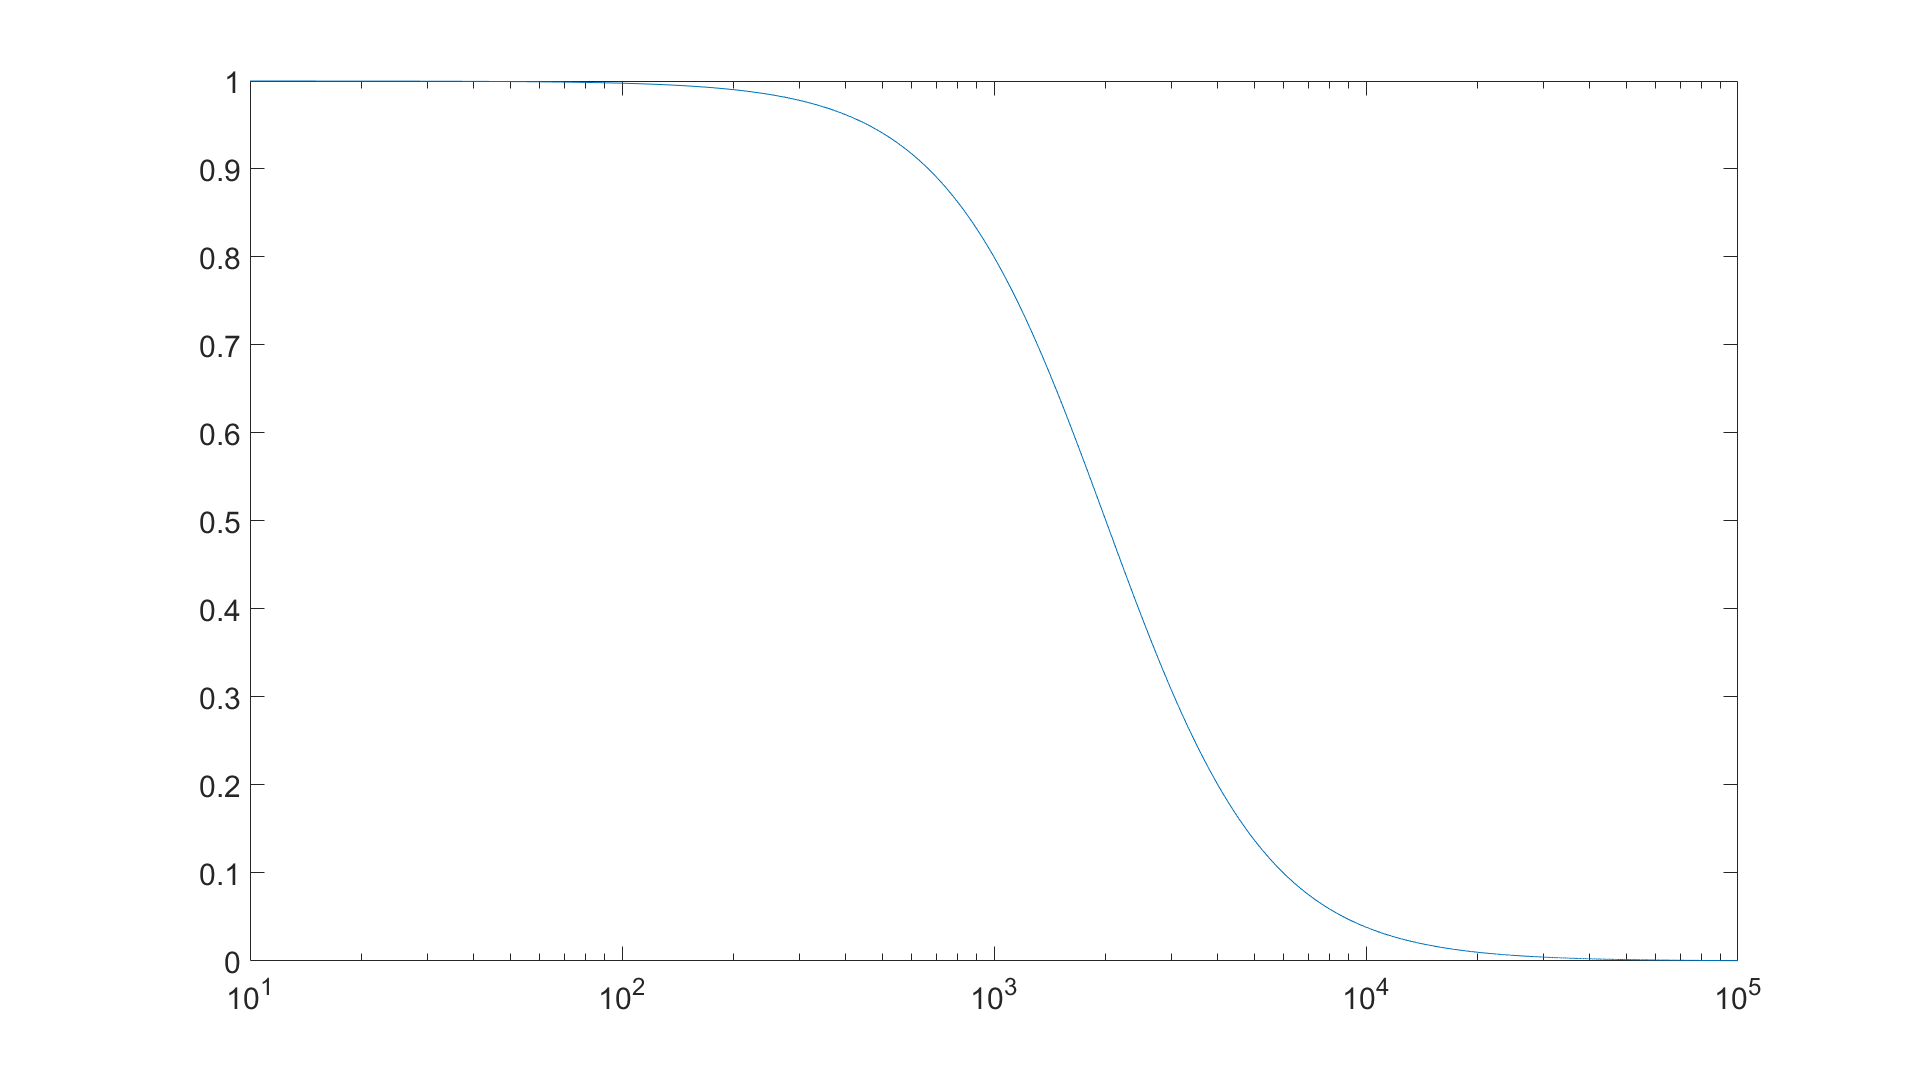

omega_0 = 2e3;
beta = 20;
psd = 2*1*beta/(1+beta)^2*1/omega_0*1./(1+(omega/omega_0).^2);
psd = psd./max(psd);
semilogx(omega,psd)

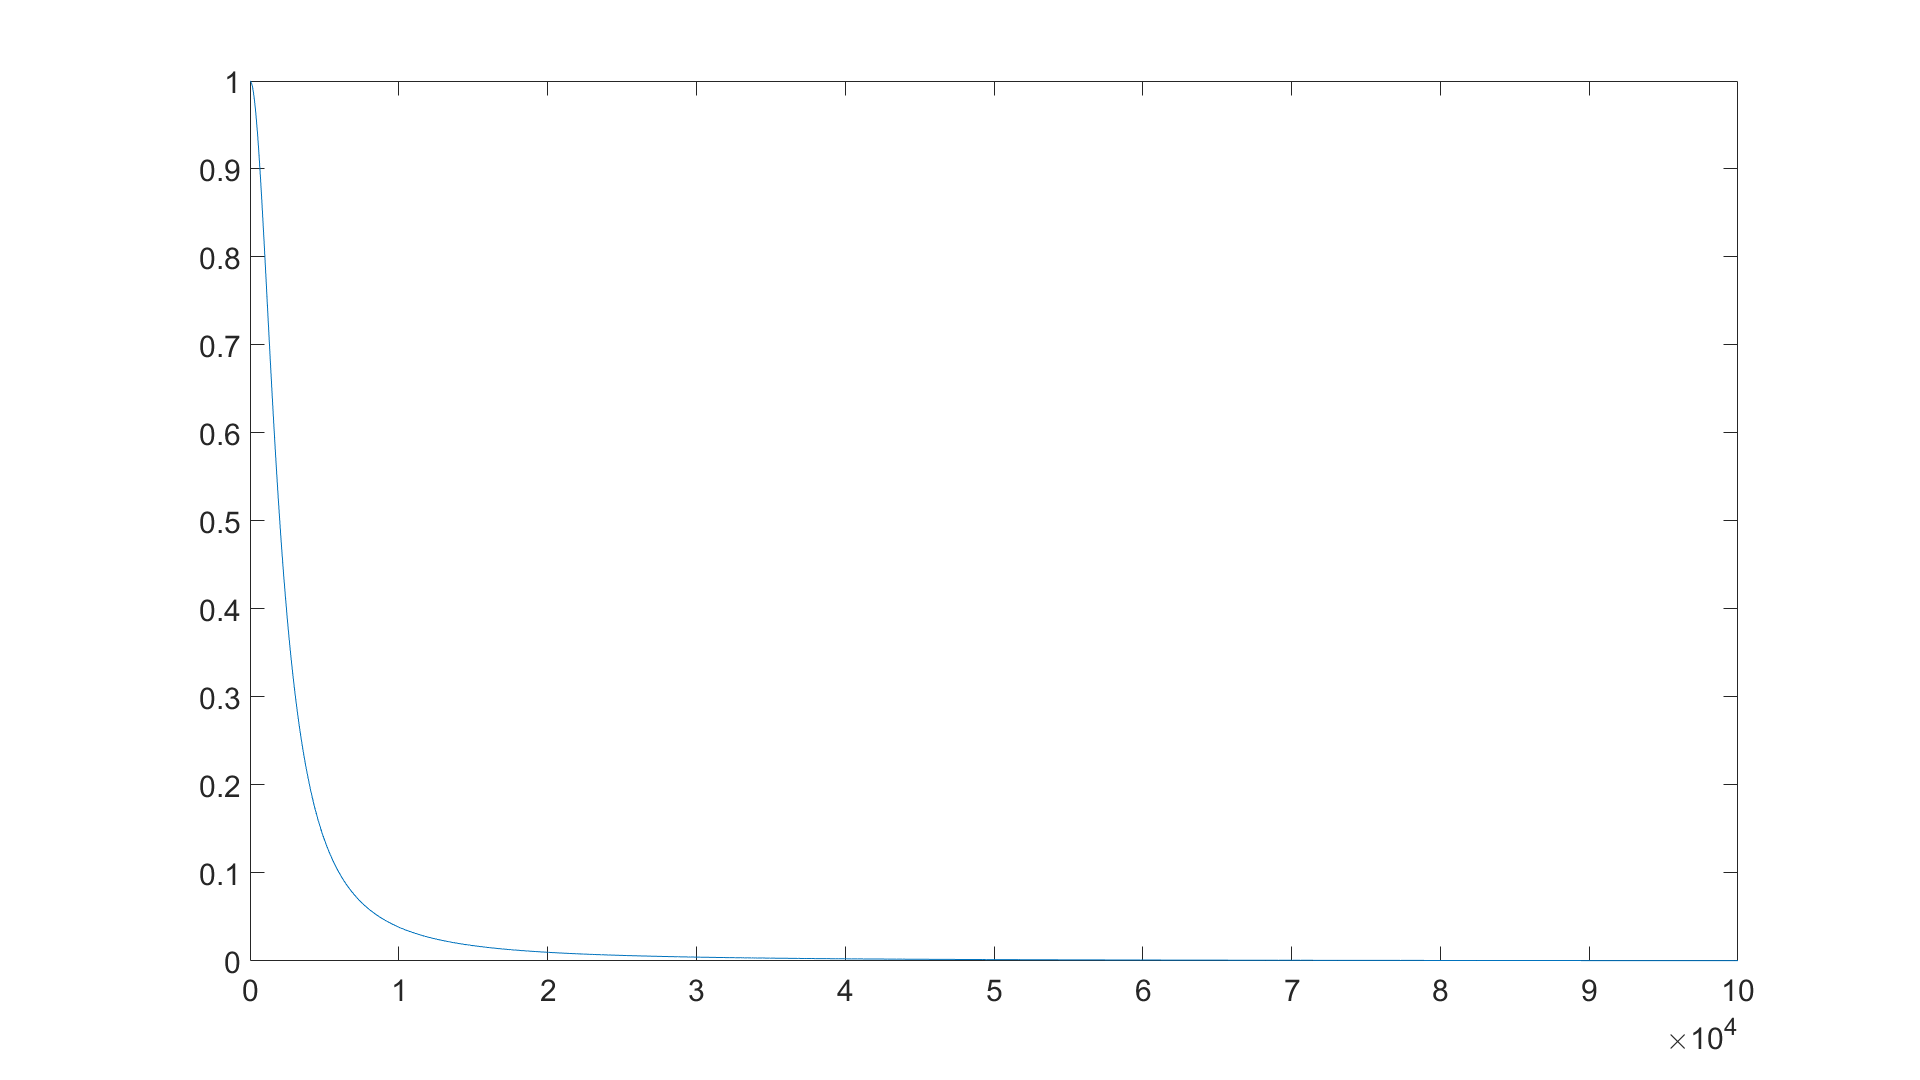

figure
plot(omega, psd)

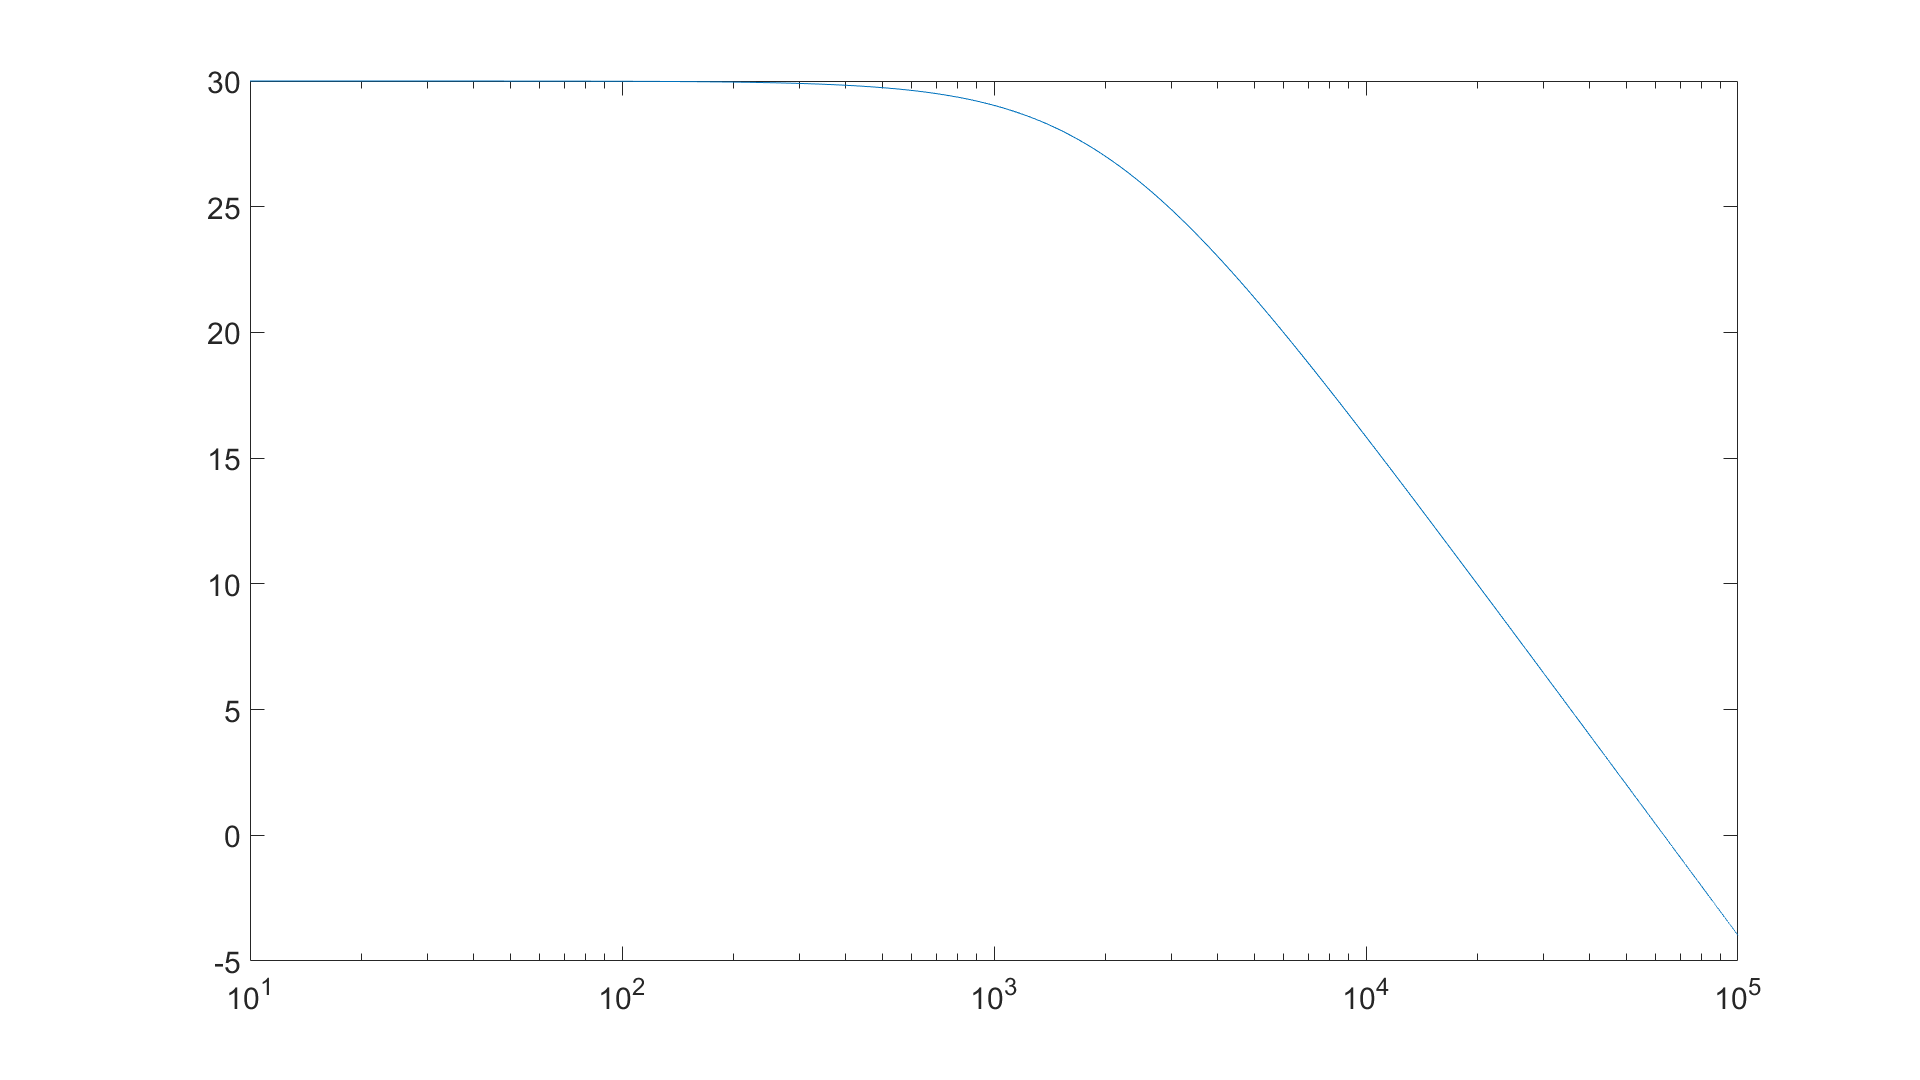

figure
semilogx(omega, 10*log10(psd/1e-3))